Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Dispersion suppressor (Section 3.7.7)

Volker Ziemann, 211119

In this example we illustrate the code that generated Figure 3.30 with the dispersion suppressor in a 90-degree FODO lattice. The suppressor consists of two FODO cells where the full-length dipole magnets are replaced by half-length dipoles.

First we need to add support for the 3D calculations...

clear all
addpath ./3D    % contains the support functions, such as calcmat() 

...and define the regular FODO cells that are used in the arcs. 

fodo=[               % regular FODO cell in arc
  2,	1,	0,	8.5511;	
  1,	5,	0.2,	0;
  4,	8,	0.5,	1;   % 8x0.5m = 4 m long dipole
  1,	5,	0.2,	0;
  2,	1,	0,	-4.2483;
  1,	5,	0.2,	0;
  4,	8,	0.5,	1;   % 4 m long dipole
  1,	5,	0.2,	0;
  2,	1,	0,	8.5511];

The FODO cell in the disp[ersion suppressor is very similar, only the dipoles are shorter and the adjacent drift spaces are a bit longer in order  to maintina the length of the cell. Note also that the quadrupoles excitations are the same in both types of cells. 

fodods=[             % FODO cell in dispersion suppressor
  2,	1,	0,	8.5511;   
  1, 10,	0.2,	0	 ;
  4,	4,	0.5,	1;      % 4x0.5m = 2 m long dipole
  1, 10,	0.2,	0;	 
  2,	1,	0,	-4.2483; 
  1,	10,	0.2,	0	 ;
  4,	4,	0.5,	1 ;     % 2 m long dipole
  1,	10,	0.2,	0;	 
  2,	1,	0,	8.5511];

Now we calculate the periodic dispersion in an arc cell, which give us the initial value `D0` for the dispersion that causes a periodic dispersion in the arcs.

beamline=fodo;    % one arc-fodo cell
[Racc,spos]=calcmat(beamline); 
Rend=Racc(:,:,end);
D0=periodic_dispersion(Rend);

In order to verify that the disperison is periodic we plot it

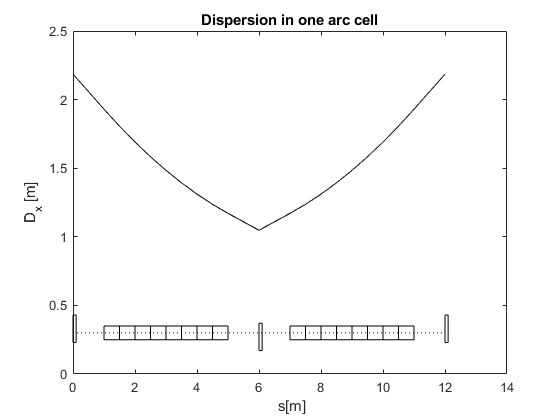

D=calculate_dispersion(beamline,D0);
plot(spos,D,'k');
xlabel(' s[m]'); ylabel('D_x [m]');
drawmag(beamline,0.2,0.2)
title('Dispersion in one arc cell')

Now we add two dispersion suppressor cells to one arc cell and calculate all transfer matrices and the positions `spos` with `calcmat()`.

beamline=[fodo;repmat(fodods,2,1)];    % one arc and two suppressor cells
[Racc,spos]=calcmat(beamline); 

Finally, we calculate the dispersion D along the beam line and plot it. For convenience, we also add the magnet lattice to show the positions of the dipoles and their respective lengths.

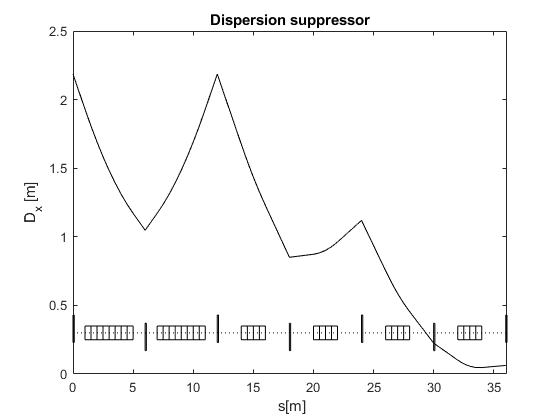

D=calculate_dispersion(beamline,D0);
figure; plot(spos,D,'k');   % Fig. 3.30
xlabel(' s[m]'); ylabel('D_x [m]');
title('Dispersion suppressor')
drawmag(beamline,0.2,0.2)
xlim([0,36.1]); 

Note that the dispersion is not perfectly zero at the end, because weak focussing of the dipoles which is slightly different for the full-length and half-length dipoles. This can be fixed by slightly changing the quadrupole excitations. 